# Minimum Airspeed for Takeoff vs Altitude

(Adapted from AE2440, AY24Q4, courtesy of Prof. Dobrokodov.)

Topics:

- Functions

- Logicals - using `find`

- `Interpolation`

- Vector element-wise arithmetic

- 2D line ploting

In this task, you need to explore and code in MATLAB the dependency of the minimum airspeed ($V_{min}
$) for takeoff of an aircraft on the runway altitude ($h_{runway}$). 

## Models:

Here is a mathematical model for the relationship:


$$V_{\text{min}} = \sqrt{\frac{ 2 M g}{\rho(h_{runway}) \, S  \,C_L}}$$


where the air density ($\rho$) is modeled with the exponential

$\rho(h) = \rho_0 e^{-\frac{h}{H}}$.

Consider the nominal falues for an F/A-18 Super Hornet.

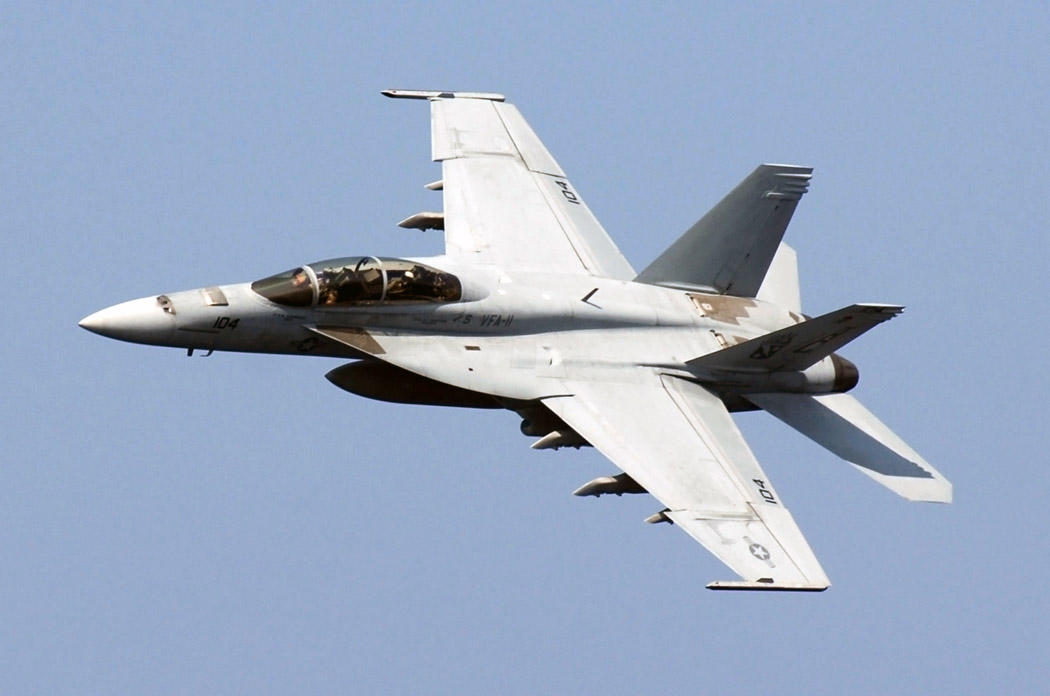

The constant coefficients are as follows:

- Lift coefficient - $C_L = 1.75$ dimensionless

- Wing surface area - $S = 37.2 \ m^2$ (per wing)

- Idealized altitude scale - $H = 8500 \ m$

- 
$$\rho_0=1.225\frac{kg}{m^3}$$


- Acceleration of gravity - $g = 9.81 \ m/s^2$

Consider two configurations for the aircraft mass

- Empty - $M = 14500 \ kg$

- Max Takeoff Weight - $M = 30000 \ kg
$

Exercises:

- Write a local function to calculate the relationship.  Input parameters: $h_{runway}$ (scalar or vector) and $M$(scalar).  Output variable: $V_{min}$ (scalar or vector). 

- Create a *well-documented* plot of the $V_{min}(h_{runway})$ for the two configurations as altitude varies 0 and 5000 m with step size of 100 m.  Use different line types, colors and line widths for the two line plots.  Inlcude a legend in a place that it doesn't obscure the information.  Include labels (with units) on the axes.

- From #2 you should have vectors for $h_{runway}$ and $V_{min}$ of equal lenght.  Use the `find` function to locate the following elements in the vectors:  For an empty aircraft with a maximum speed of 70 m/s, what is the maximum runway altitude for which it can take off?  For an aircraft at max. weight that is limited to 90 m/s, what is the maximum runway altitude?  Programmatically annotate your original figure with these two points with markers. 

- Repeat #3 using the  `interp1 function, adding a second marker on each line.`

function vmin = takeoff_speed(h, m)

ans = 59.7276

    % Minimum take off speed as a function of airstrip altitude and mass.
    CL = 1.75;

ans =    59.7276   80.1509


    S = 37.2;
    g = 9.81;
    H = 8500;
    rho_o = 1.225;
    rho = rho_o * exp(-h/H);
    vmin = sqrt( (2*m*g) ./ (rho*S*CL) );
end

Follwing incremental development, let's try this out before moving ahead.  Recall that 1 m/s ~ 2 kts.  Does it work for scalar input?

takeoff_speed(0, 14500)

How about for vector input?  We expect that as altitude increases, density decreases, so would need more airspeed to takeoff.

takeoff_speed([0 5000], 14500)

## Plot using vectors.

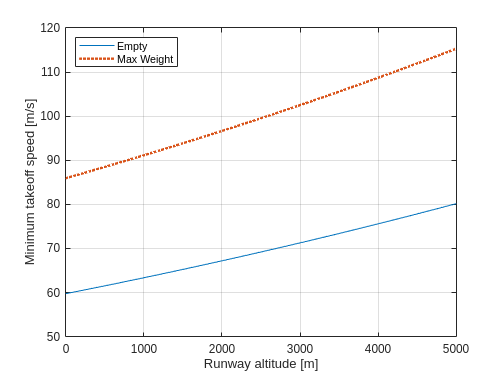

figure;
hh = 0:100:5000; % m
vmin_empty = takeoff_speed(hh, 14500);

vmin_full = takeoff_speed(hh, 30000);
p_empty = plot(hh,vmin_empty, 'DisplayName', 'Empty');
hold on
p_full = plot(hh,vmin_full,':', 'DisplayName', 'Max Weight', 'LineWidth', 2);
grid('on')
legend([p_empty p_full], 'Location', 'northwest')
xlabel('Runway altitude [m]')
ylabel('Minimum takeoff speed [m/s]')

## Find values

Finding values in two equal sized arrays,  Find the indexes corresponding to the condition. 

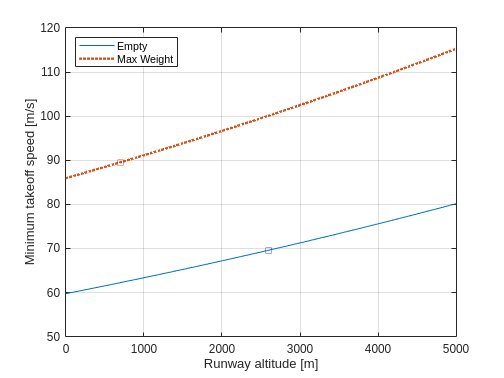

ii = find(vmin_empty <= 70);

plot(hh(ii(end)), vmin_empty(ii(end)),'bs')
jj = find(vmin_full<=90);
plot(hh(jj(end)), vmin_full(jj(end)), 'rs')
% Optional: repeat the legend command to prevent MATLAB from adding more
% entries
legend([p_empty p_full], 'Location', 'northwest')

## Interpolation

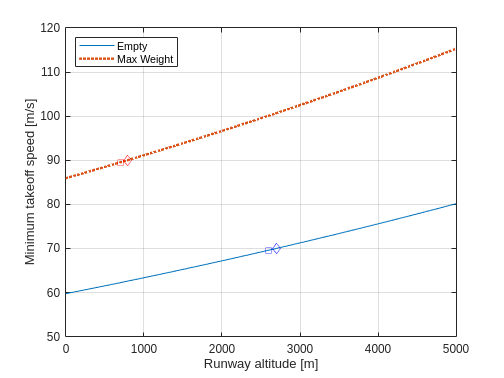

max_speed = 70;
h_max_empty = interp1(vmin_empty, hh, max_speed);
plot(h_max_empty, max_speed, 'bd')

max_speed = 90;
h_max_full = interp1(vmin_full, hh, max_speed);
plot(h_max_full, max_speed, 'rd');
legend([p_empty p_full], 'Location', 'northwest')